# Electric scooter parameters

Energy Engineering 3rd grade PBL scooter.

This file gathers parameter values for electric scooter components.

clear all

## Electric motor parameters

[MY1020](https://www.alibaba.com/product-detail/MY1020-500W-24V-Electric-Tricycle-Go_62081875552.html?spm=a2700.shop_plser.41413.12.29c247c0g6Dloj) motor parameters

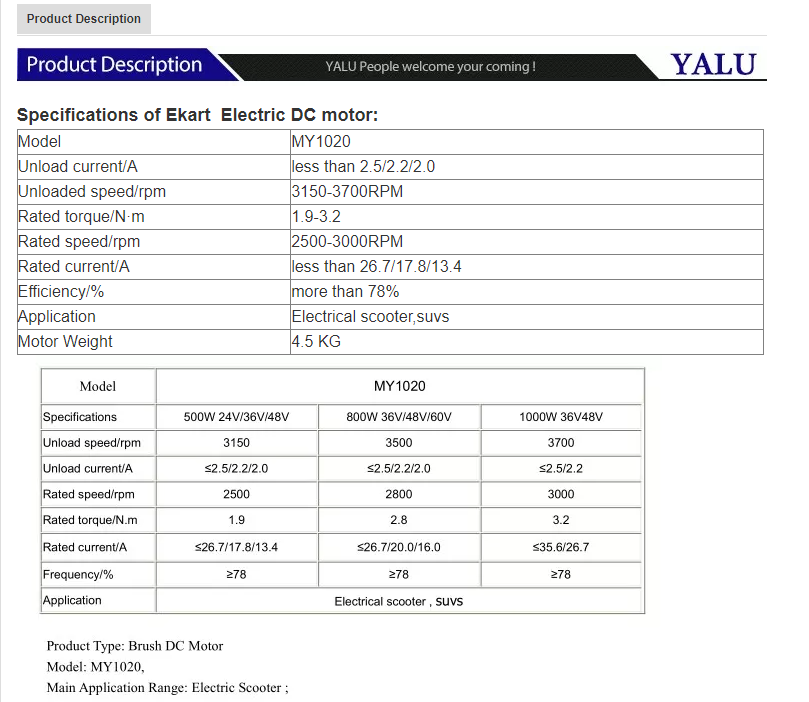

Pnom = 500;                 % Nominal power [W]
Tnom = 1.9;                 % Nominal torque [Nm]
Nnom = 2500;                % Nominal speed [rpm]
Vnom = 24;                  % Nominal voltage [V]
Nm_noLoad = 3150;
wm_noLoad = Nm_noLoad*pi/30;
Ke = 0.074965;              % Voltage constant [V]               

% Inom = 26.7;                % Nominal current [A]
Kt = Ke;                    % Voltage constant [V/rad/s]
eff_mot = 0.78;             % Motor efficiency
Inom = Tnom/Kt;             % Nominal current

We will estimate resistance from efficiency and power. For a DC motro


$$P_a =V_a \cdot I_a =R_{a\;} \cdot I_a^2 +K_e \cdot I_{a\;} \cdot \;\Omega {\;}_m =\left(R_a \cdot I_a +K_e \cdot \Omega {\;}_m \right)\cdot I_a$$



$$\begin{array}{l}
P_a =\textrm{input}\;\textrm{power}\\
P_r =\textrm{resistor}\;\textrm{losses}\;R_{a\;} I_a^2 \\
P_m =\textrm{mechanical}\;\textrm{power}\;T_{\textrm{em}} \cdot \Omega {\;}_m \\
\eta =\frac{P_m }{P_a }
\end{array}$$


We suppose that motor efficiency takes into account only electrical losses:

Pa = Pnom;          % Input electrical power [W]
Pm = eff_mot*Pa;     % Output mechanical power [W]
Pr = Pa - Pm;        % Resistor losses [W]
Ra = 0.142174119;   % Armature resistance [Ohm]
% Unknown-n parameters
Ipeak = Inom*2;             % Peak current [A]
Tpeak = Ipeak*Kt;        % Peak torque [Nm]
La = 0.000227479;                % Armature inductance [H]
Jm = 2.60E-03;             % Motor inertia [kg*m^2]
tau_e = La/Ra;            % Electrical time constant [s]
tau_m = 104e-3;             % Mechanical time constant of the motor [s]
Kf = 0.1635;                % Static motor friction [Nm]
D = 0.0104;                 % Viscous friction [Nm/rad/s]

### Torque-speed curve

Manufacturer does not give motor resistance value. We can obtain it from the stall torque:

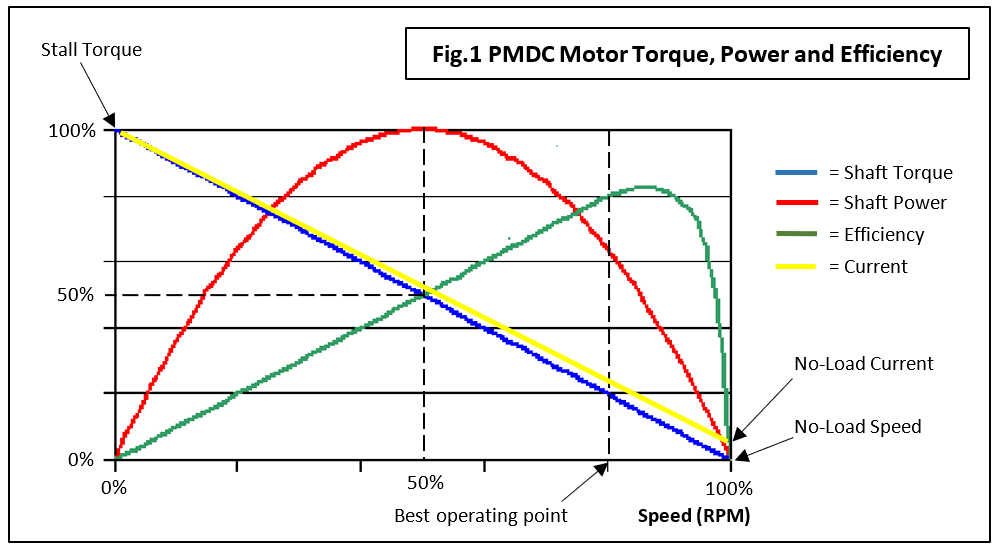

The torque-speed curve is:


$$T_m =\frac{-K_t K_e }{\;R_a }\omega {\;}_m +\frac{K_t }{R_a }v$$


No load speed (approximation because at no load, the motor should make enough torque to overcome viscous friction with no load current):


$$0=\frac{-K_t K_e }{\;R_a }\omega {\;}_m +\frac{K_t }{R_a }v\to \frac{V_{\textrm{nom}} }{K_e }=\omega {\;}_{\textrm{noLoad}}$$


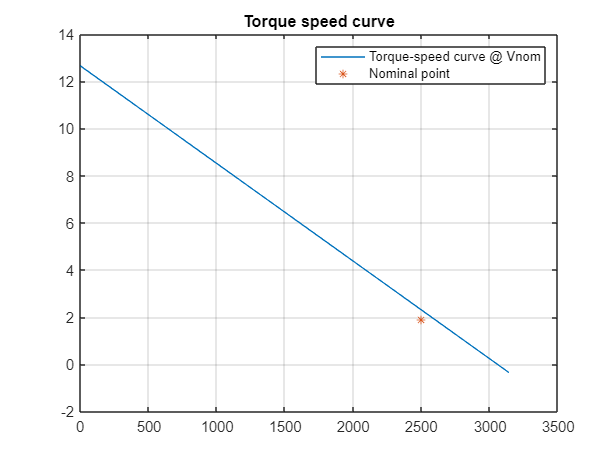

wm = 0:1:wm_noLoad;
Tm = -Kt*Ke/Ra.*wm+Kt/Ra*Vnom;
figure
plot(wm*30/pi,Tm);
hold on
plot(Nnom,Tnom,'*')
grid
legend('Torque-speed curve @ Vnom','Nominal point')
title('Torque speed curve')

## Mechanical system configuration

The proposed mechanical system was developed in Low Power Electric Two-Wheelers for Hilly Region

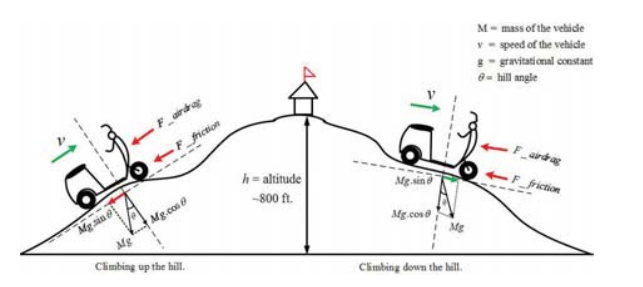

The main equation that describes the linear motion is:


$$F_{\textrm{wheel}} -F_{\textrm{rolling}} -F_{\textrm{drag}} -F_{\textrm{hc}} =m_{\textrm{total}} \cdot a_{\textrm{scooter}}$$


Where:

- $F_{\textrm{scooter}}$ is the force applied by the scooter in the wheel.


$$T_m \;\textrm{is}\;\textrm{the}\;\textrm{torque}\;\textrm{in}\;\textrm{the}\;\textrm{motor}\;\textrm{shaft}\;\left(\textrm{after}\;\textrm{motor}\;\textrm{mechanical}\;\textrm{losses}\right)$$



$$\left\lbrace \begin{array}{ll}
T_{\textrm{scooter}} =T_m \cdot n_{\textrm{gear}} \cdot {\textrm{eff}}_{\textrm{gear}}  & \;\textrm{traction}\\
T_{\textrm{scooter}} =T_m \cdot \frac{n_{\textrm{gear}} }{{\textrm{eff}}_{\textrm{gear}} } & \textrm{breaking}
\end{array}\right.$$


DC motor mechanical losses could be taken into account. Search the percentage over total.

- $F_{\textrm{rolling}}$ is the rolling resistance made by the contact between the wheel and the road. 


$$F_{\textrm{rolling}} =C_{\textrm{rr}} \cdot N=C_{\textrm{rr}} \cdot m_{\textrm{total}} \cdot g\cdot \cos \left(\theta \;\right)$$


- $F_{\textrm{drag}}$ is the drag resistance of the air.


$$F_{\textrm{drag}} =\frac{1}{2}\rho \;{\textrm{AC}}_d v^2$$


- $F_{\textrm{hc}}$ is the hill climbing resistance force due to the hill.


$$F_{\textrm{hc}} =M\cdot g\cdot \sin \left(\theta \right)$$


### Parameters

m_frame = 15;                       % Scooter frame and battery mass [kg]
m_motor = 5.5;                     % DC motor mass [kg]
m_scooter = m_frame + m_motor;      % Scooter mass [kg]
m_driver = 75;                      % Driver mass [kg]
m_total = m_scooter + m_driver;     % Total mass of scooter with driver [kg]
Rwheel = 0.2032;                    % Wheel radious [m] 16 inch diameter wheel
n_teeth_pinion = 11;                 % Pinion teeth number
n_teeth_gear = 65;                  % Gear teeth number
n_gear = n_teeth_gear/n_teeth_pinion; % Transmission system ratio
eff_gear = 0.97;                    % Gear efficiency
v_wheel_max_kmh = 25;               % Maximum scooter speed [km/h]
v_wheel_max = v_wheel_max_kmh/3.6;  % Maximum scooter speed [m/s]
w_wheel_max = v_wheel_max/Rwheel;    % Maximum wheel angular speed [rad/s]
w_motor_max = w_wheel_max*n_gear;    % Maximum motor angular speed [rad/s]
w_motor_max_rpm = w_motor_max*30/pi;    % Maximum motor angular speed [rpm]

### Equivalent moment inertia calculation

In order to obtain an equivalent transfer function for loop tunning, load and wheel equivalent inertia must be obtained in the motor axis.

The inertia elements in this system are:

- Passenger and scooter mass. Taken as half per each wheel.

- Wheel moment of inertia is discarded.

- Motor inertia.

- Efficiency of drive chain is not taken into account for speed loop tunning.

J_driverFrame = (m_scooter/2+m_driver/2)*Rwheel^2;       % Moment of inertia for mass in angular movement [kg*m^2]
J_eq = J_driverFrame/n_gear^2;                          % Equivalent moment of inertia of driver and frame [kg*m^2]
J_total = J_eq + Jm;                                     % Equivalent total moment of inertia [kg*m^2]
tau_m_eq = J_total/D                                     % Equivalent time constant for the whole system [s]. Only taking into account the viscous friction in motor

tau_m_eq = 5.6793

### Rolling resistance

Crr = 0.0025;                       % Rolling resistance coefficient

### Drag friction

Cd = 0.7;                           % Drag resistance coefficient
rho = 1.225;                        % Air density [kg/m^3]
A = 0.6;                            % Scooter and driver frontal area [m^2]

### Road characteristics

g = 9.81;               % Gravity [m*s^2]
slope = 0*pi/180;     % Slope [rad]

## Power electronics parameters

Vbat = 24;              % Battery nominal voltage
fsw = 10e3;             % Chopper switching frequency

## Control configuration

load controllerParams

## Simulation configuration

Ts_mf = 20e-6; %tau_e/100;          % Medium fidelity simulation step [s]
Ts_lf = tau_m_eq/100;       % Low fidelity simulatoin step [s]
Ts_hf = (1/fsw)/100;         % High fidelity simulation step [s]
Tcontrol = 200e-6;          % Control execution time [s]
close all